Initialization

clc;clear;close all

safety_value = 1.5;

% TODO: are these finalized?
m = 9345; % [kg]
W = m * 9.81 * safety_value; % [N]
taper_ratio = 0.6;
c1 = 2.86; % [m] Base chord length
c2 = c1 * taper_ratio; % [m] Tip chord length
c_average = (c1 + c2) / 2;
b = 18; % [m] Wing span (both wings)
S_w = (c1 + c2)/2 * b; % [m^2]
e = 0.98; % [-]
AR = b^2 / S_w; % [-]
landing_gear_height = 1.5; % [m]
poissons_ratio = 0.3;

L = b / 2; % [m]

Now we calculate the lift distribution

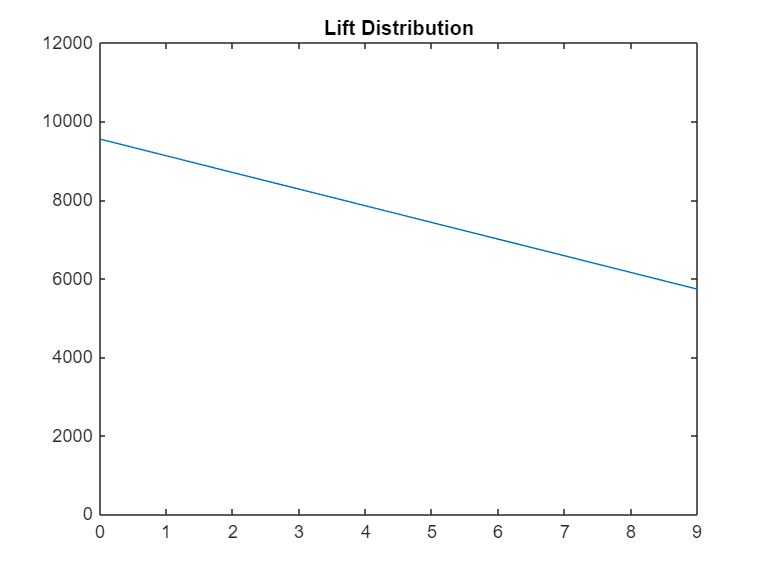

syms x
n = 20;
c = c1 - (c1-c2)*(x/L);

distributed_lift = W / S_w * c; % [N/m]

F_R = W/2;


figure
fplot(distributed_lift, [0, L])
title('Lift Distribution')
axis([0 L 0 12000])

Calculating the internal shear

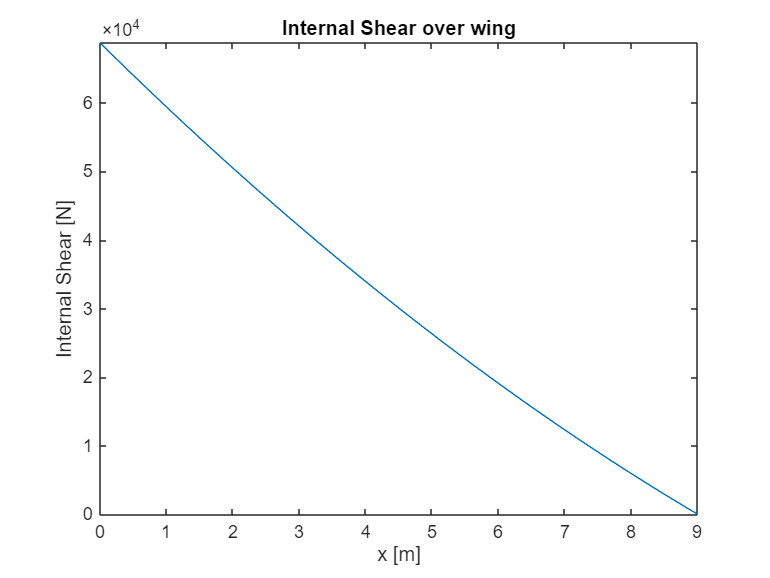

S = int(distributed_lift, x, 0, x) - F_R;
figure
fplot(-S, [0, L])
title('Internal Shear over wing')
ylabel('Internal Shear [N]')
xlabel('x [m]')

Calculating internal moment

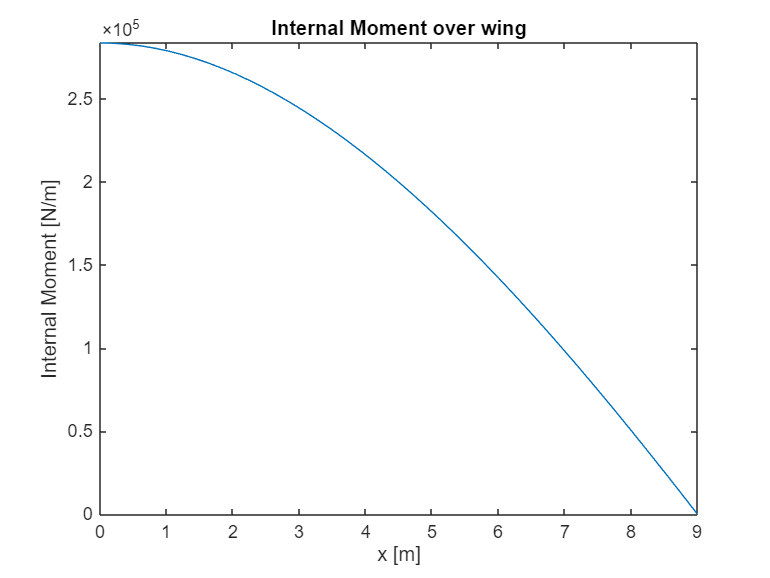

M_R = int(x * distributed_lift, x, 0, L);
M = M_R - int(x * distributed_lift, x, 0, x);
figure
fplot(M, [0, L])
title('Internal Moment over wing')
ylabel('Internal Moment [N/m]')
xlabel('x [m]')


% The moment function is a 3rd order polynomial
assert(polynomialDegree(M) == 3)

Defining spar properties and calculating bended wing shape

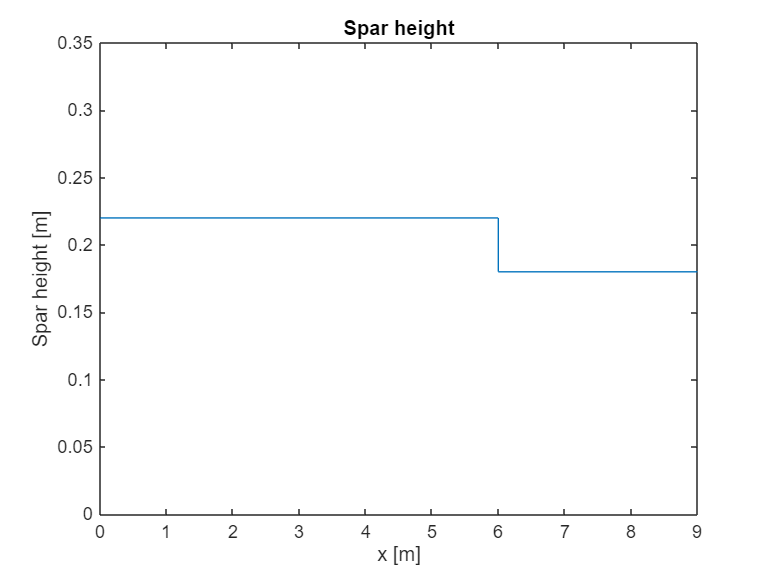

spar.t = 25e-3; % [m]
spar.h1 = 220e-3; % [m]
spar.h2 = 180e-3; % [m]
spar.h = piecewise(x < 2/3*L, spar.h1, spar.h2);
spar.w = spar.h * 1.3; % [m]
spar.w1 = double(subs(spar.w, x, 0));
spar.w2 = double(subs(spar.w, x, 9));
spar.I = spar.t*spar.h^3 / 12 + spar.w*spar.t*spar.h^2 / 2;
spar.E = 210e9; % [Pa]

figure
fplot(spar.h, [0, L])
title('Spar height')
ylabel('Spar height [m]')
xlabel('x [m]')
axis([0 L 0 0.35])

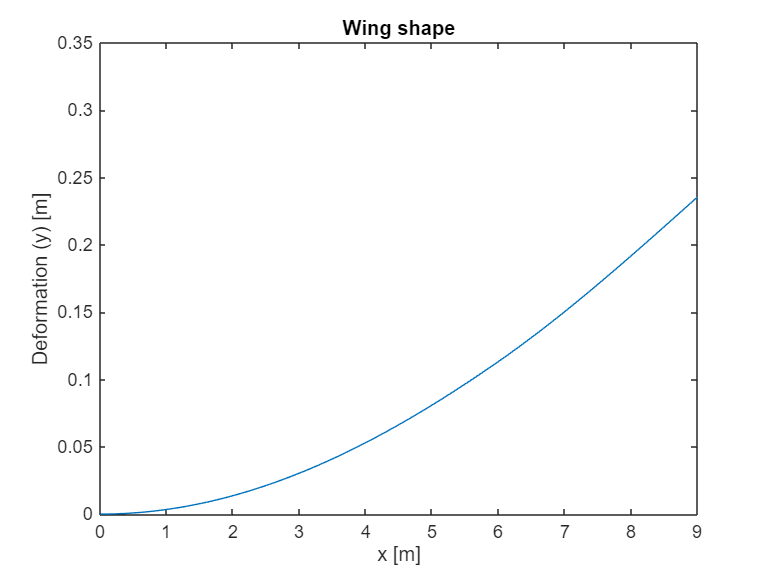


d2ydx2 = M / (spar.E*spar.I);
dydx = int(d2ydx2, x, 0, x);
y = int(dydx, x, 0, x);

figure
fplot(y, [0, L])
ylim([0 0.35])
title('Wing shape')
ylabel('Deformation (y) [m]')
xlabel('x [m]')

Calculating maximum wing stress.

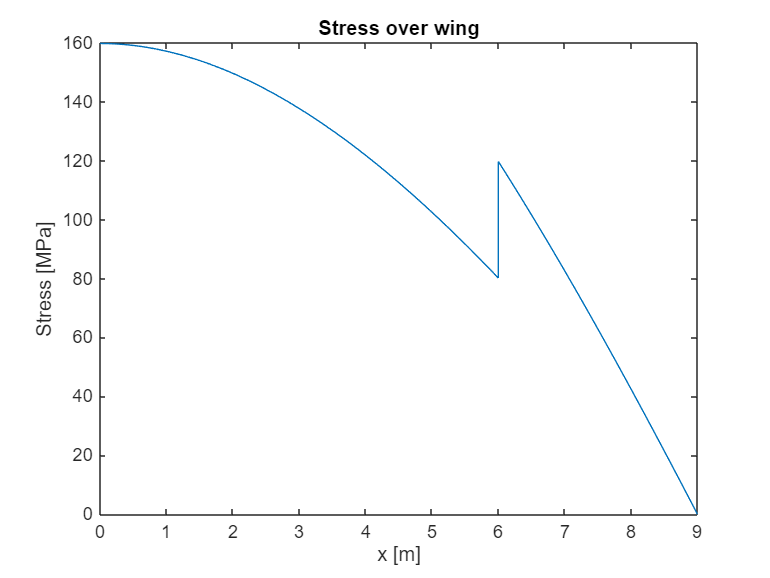

stress = M * spar.h/2 / spar.I;
figure
fplot(stress/1e6, [0, L])
title('Stress over wing')
ylabel('Stress [MPa]')
xlabel('x [m]')

Calculating the strain at the top of the wing. This is done so that buckling calculations can be done for the top and bottom of the wing.

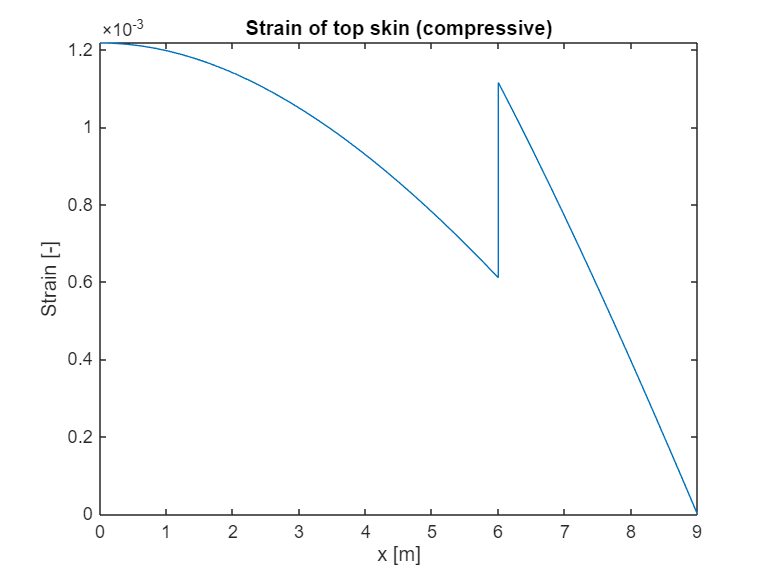

strain = d2ydx2 * 0.176; % Distance between the centerline and the top of the wing

figure
fplot(strain, [0, L])
title('Strain of top skin (compressive)')
ylabel('Strain [-]')
xlabel('x [m]')

Now we go on to find out what should be the spacing of the ribs. We assume that the skin with stringers rotates along the plane of the skin. Because of this we can also assume that most of the bending stiffness comes from the stringers. And the skin with stringers can rotate at it's connection point with the ribs.

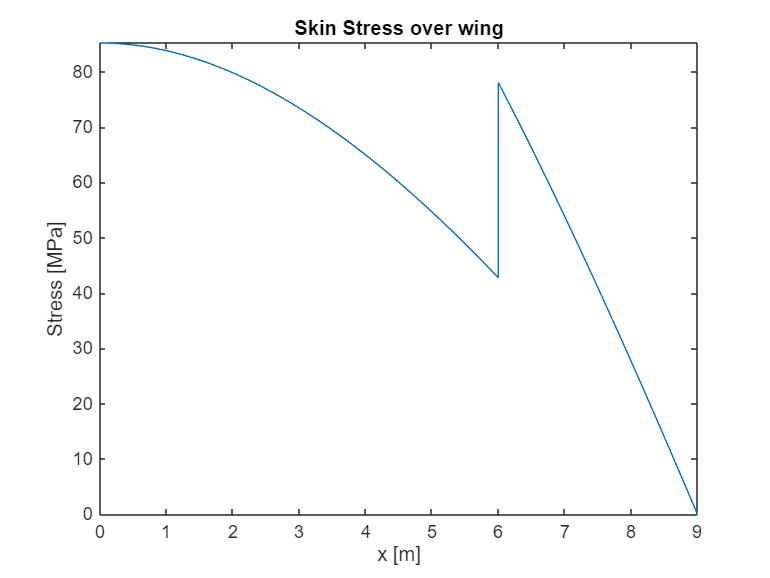

stringers.t = 3e-3; % [m]
stringers.h = 50e-3; % [m]
stringers.w = 50e-3; % [m]
stringers.I = stringers.t * stringers.h^3 / 3; % [m^4]
E_aluminium = 70e9; % [Pa]
stringers_spacing = 0.09; % [m] Distance between stringers
skin_thickness = 1.8e-3;
skin_stress = E_aluminium * strain;
stringer_section_area = (stringers.h+stringers.w)*stringers.t + skin_thickness*stringers_spacing; % [m^2] per stringer
stringer_section_force = skin_stress * stringer_section_area;

figure
fplot(skin_stress/1e6, [0, L])
title('Skin Stress over wing')
ylabel('Stress [MPa]')
xlabel('x [m]')

rib_spacing = sqrt(pi^2 * E_aluminium * stringers.I / stringer_section_force);

figure
fplot(rib_spacing, [0, L])
title('Required Max Rib Spacing over wing')
ylabel('Distance between ribs [m]')
xlabel('x [m]')
axis([0 L 0 7])

Judging by this the distance between ribs cannot be larger than 1 meter. Since this value does not significantly go up it makes sense to make the rib spacing constant at 1 meter.

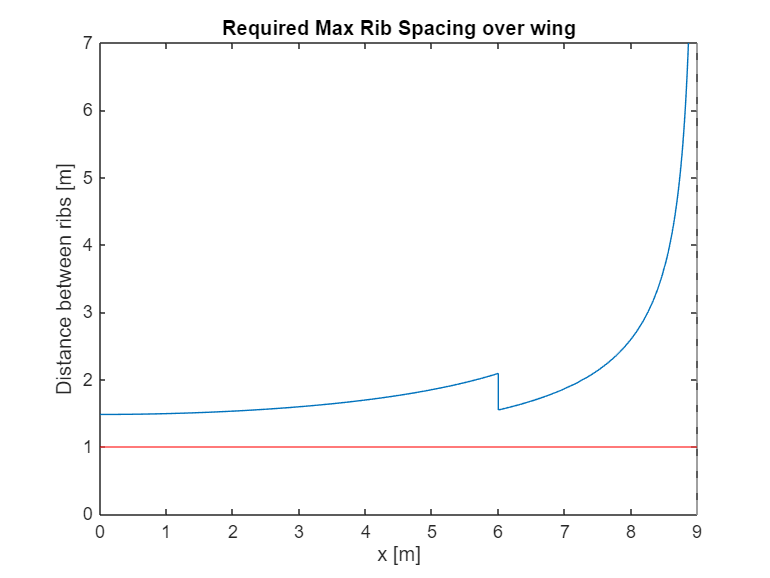

rib_spacing = 1; % [m]
yline(rib_spacing, 'r')

Now we are going to take a look at local buckling

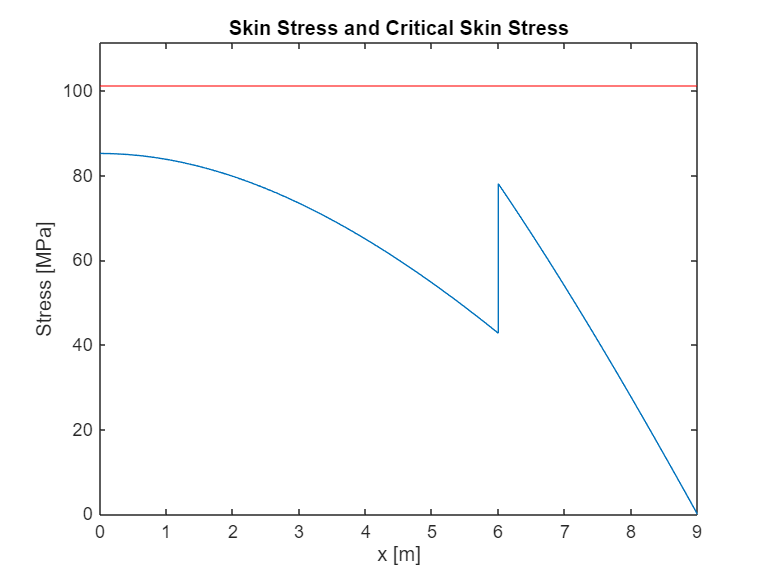

a = rib_spacing;
b = stringers_spacing;
aspect_ratio = a/b;
m = aspect_ratio; % Taken from chart in slide (24)
k = (m*b/a + a/(m*b))^2;
skin_stress_crit = k * pi^2 * E_aluminium / (12 * (1-poissons_ratio^2)) * (skin_thickness / b)^2;

figure
fplot(skin_stress/1e6, [0, L])
yline(skin_stress_crit/1e6, 'r')
axis([0 L 0 skin_stress_crit/1e6*1.1])
title('Skin Stress and Critical Skin Stress')
ylabel('Stress [MPa]')
xlabel('x [m]')

Now we are going to make a diagram of the wings. For that a single simulation is done. The input for this does not have to accurate since only the shape of the airfoil is extracted.

sim.Re = 9.7e6;
sim.alpha = 0;
sim.Mach = 0.3;

[~, airfoil] = xfoil('NACA 2412',sim.alpha,sim.Re,sim.Mach,'oper iter 60','ppar N 181','oper xtr 0.1 0.1');

C:\Users\joran\Documents\GitHub\mod10project\xfoil


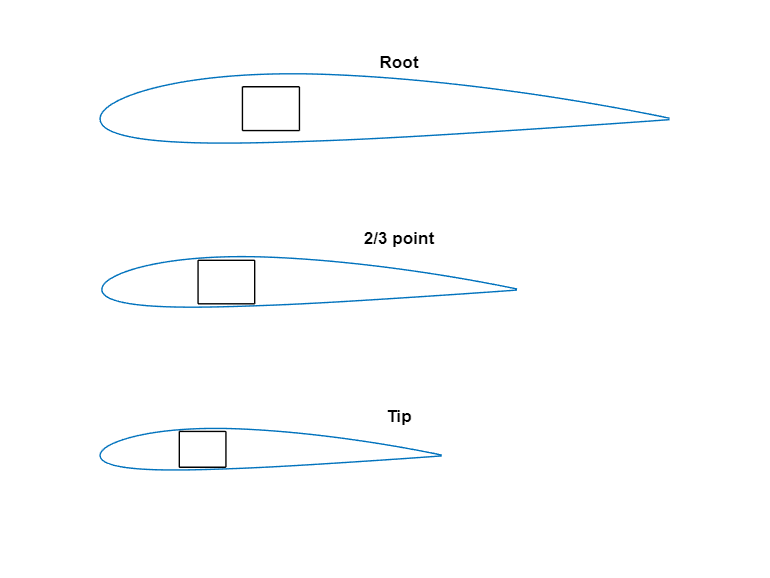


spar_center = [0.3, 0.018];
%% f
figure
tiledlayout(3,1)
nexttile
title('Root')
plotfoil(airfoil, c1)
xlim([0 3])
rectangle('Position',[-spar.w1/2+spar_center(1)*c1, -spar.h1/2+spar_center(2)*c1, spar.w1, spar.h1])
title('Root')
axis off

nexttile
c23 = c1 - (c1 - c2)*(2/3);
plotfoil(airfoil, c23)
xlim([0 3])
rectangle('Position',[-spar.w1/2+spar_center(1)*c23, -spar.h1/2+spar_center(2)*c23, spar.w1, spar.h1])
title('2/3 point')
axis off

nexttile
plotfoil(airfoil, c2)
xlim([0 3])
rectangle('Position',[-spar.w2/2+spar_center(1)*c2, -spar.h2/2+spar_center(2)*c2, spar.w2, spar.h2])
title('Tip')
axis off